# Summary Results Demo

Use `SummaryResults` function to compare the costs values for the diferent states or resource samples of the plant

#### Select and read the data model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(filename);

#### Set Study Case

States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(1));
if data.isResourceCost
    Samples=convertCharsToStrings(data.SampleNames);
    Sample=convertStringsToChars(Samples(2));
end

#### Get all available tables depending on the data model

res=SummaryResults(data,'State',State,'ResourceSample',Sample);
StudyCase(res);

     State: 'REF'
    Sample: 'Internal'



summaryTables(res);

Summary Tables: ALL



ShowResults(res);


Flows Exergy (kW) - SUMMARY

 key            REF      TRB75     PBLR18      PCND2      PCND3      noIHE
———————————————————————————————————————————————————————————————————————————
 B1          83.570     89.430     83.930     87.640    108.000     83.570
 B2          17.900     19.540     18.460     21.920     41.990     17.900
 B3          15.790     16.940     16.390     19.590     38.680     17.900
 B4           5.784      6.190      6.011      6.340      9.990      5.784
 B5           7.877      8.430      7.948      8.528     12.620      7.877
 B6           9.420     10.310      9.471     10.330     15.490      7.877
 QBLR       100.000    106.300    100.800    103.500    120.200    106.900
 WP           2.447      2.619      2.264      2.554      3.053      2.447
 WN          50.000     50.000     50.000     50.000     50.000     50.000
 QCND        10.006     10.750     10.379     13.250     28.690     12.116


Process Unit Consumption (J/J) - SUMMARY

 key           REF      T

#### Show State Graphs

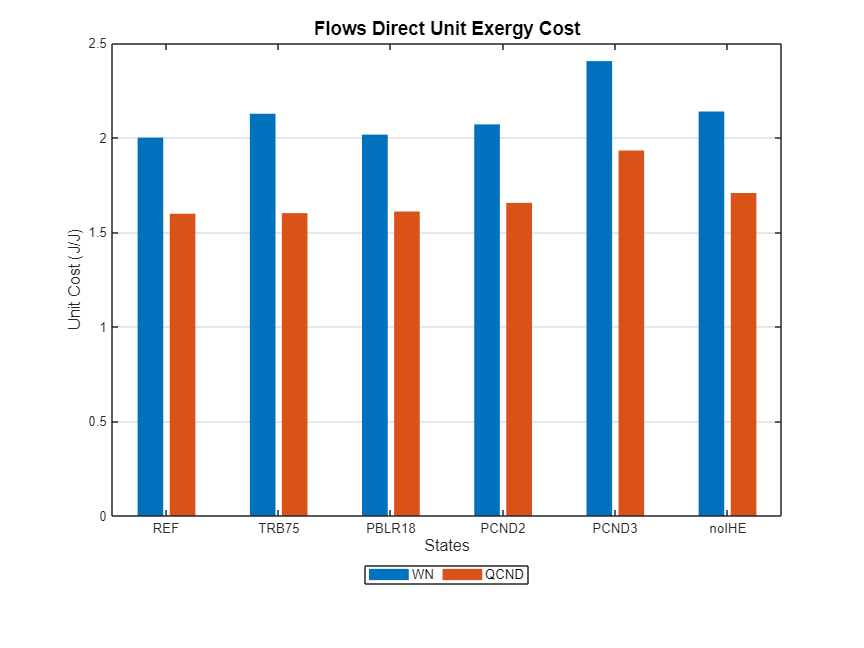

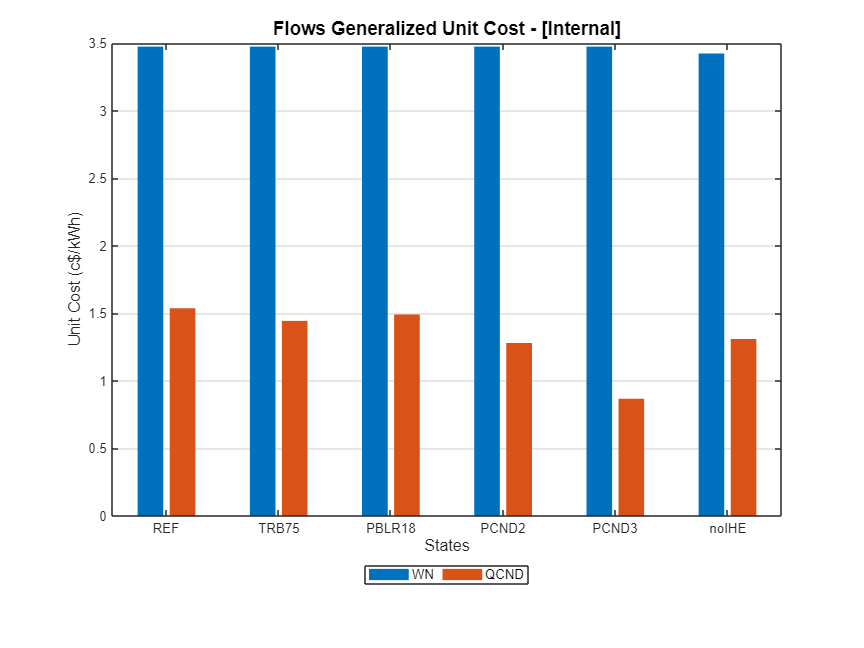

if res.isStateSummary
    ShowGraph(res,'Graph',cType.Tables.SUMMARY_FLOW_UNIT_COST);
    ShowGraph(res,'Graph',cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);
end

#### Show Resource Samples Graphs

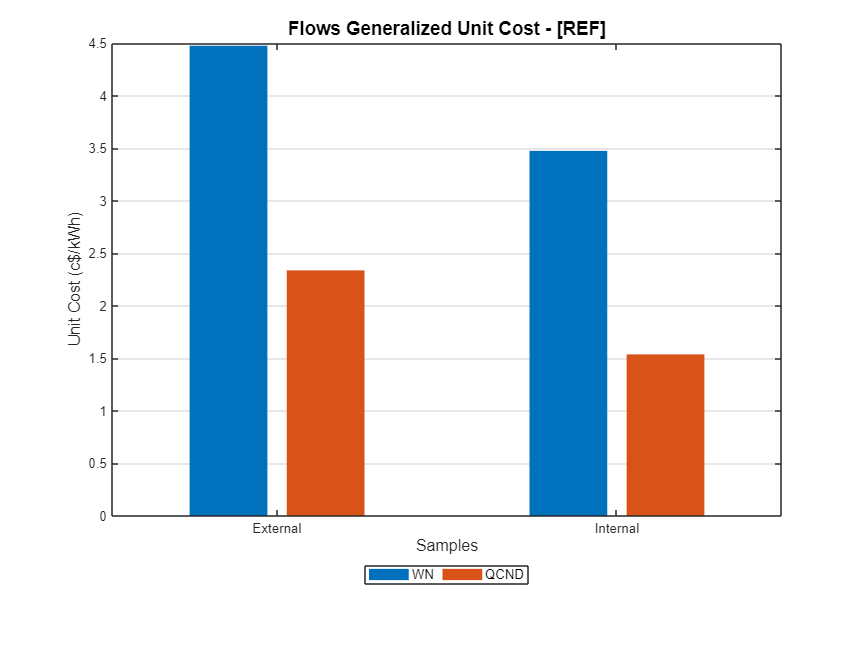

if res.isSampleSummary
    ShowGraph(res,'Graph',cType.Tables.RSUMMARY_FLOW_GENERAL_UNIT_COST);
end

#### Save the summary results into an excel file

outfile='SummaryResults.xlsx';
SaveOption=false;
if SaveOption
    SaveResults(model,outfile);
end

**Additional Help**

help SummaryResults

 SummaryResults - Gets the summary cost results for a plant.
    This function retrieves the summary tables comparing of the model
      There is to types of Summary Result Tables:
       - STATES: Comparing cost values for the diferent states
       - RESOURCES: Comparing cost values for the diferent resources samples
 
  Syntax
    res=SummaryResults(data,Name,Value)
 
  Input Arguments
    data - cReadModel object containing the data model
 
  Name-Value Arguments
    Summary - Type of Summary to obtain
      'NONE' No summary results are obtained
      'STATES' State summary is obtained
      'RESOURCES' Resources summary is obtained
      'ALL' Both summary reports are obtained 
    States - Select a state in the States table. If missing first state is taken
    ResourceSample - Select a sample in ResourcesCost table. If missing first sample is taken
      char array
    Show -  Show results on console
      true | false (default)
    SaveAs - Nam